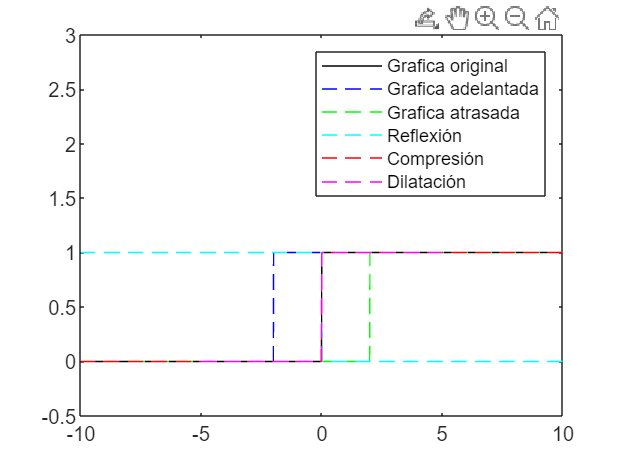

% Crear un vector de tiempo
t = -10:0.01:10;

% Inicializar un vector delta del mismo tamaño que t
delta = zeros(size(t));

% Crear la función delta(t)
for i = 1:length(t)
    if t(i) >= 0
        delta(i) = 1;
    end
end

% Graficar la función delta(t) y sus transformaciones
figure;
title('Función Delta(t) y Transformaciones');
xlabel('Tiempo');
ylabel('\delta(t)');
grid on;

% Graficar la función delta(t) original
plot(t, delta, "k", 'DisplayName', 'Grafica original');
hold on;

% Graficar la función delta(t) adelantada
plot(t-2, delta, "--b", 'DisplayName', 'Grafica adelantada');

% Graficar la función delta(t) atrasada
plot(t+2, delta, "--g", 'DisplayName', 'Grafica atrasada');

% Graficar la función delta(t) reflejada
plot(-t, delta, "--c", 'DisplayName', 'Reflexión');

% Graficar la función delta(t) comprimida
plot(t*2, delta, "--r", 'DisplayName', 'Compresión');

% Graficar la función delta(t) dilatada
plot(t/2, delta, "--m", 'DisplayName', 'Dilatación');

axis([-10 10 -0.5 3]);
legend;